# Estimate Model Parameters Using Multiple Experiments (Code)

This example shows how to estimate model parameters from multiple sets of experimental data. You estimate the parameters of a mass-spring-damper system.

## Open the Model and Get Experimental Data

This example uses the `sdoMassSpringDamper` model. The model includes two integrators to model the velocity and position of a mass in a mass-spring-damper system.

open_system('compareModels');

## Define the Estimation Experiments

Exp = sdo.Experiment('compareModels');
% create an sdo.Experiment object with only the ModelName property filled

Create an object to store the measured output.

mAbDiffrence = Simulink.SimulationData.Signal;
% create a Simulink.SimulationData.Signal object
texp = 1:169;
yexp = zeros(169,1);
mAbDiffrence.Values = timeseries(yexp,texp);

mAbDiffrence.BlockPath = 'compareModels/Subtract';
mAbDiffrence.PortType  = 'outport';
mAbDiffrence.PortIndex = 1;
mAbDiffrence.Name      = 'mAbDifference'; % define the name of the signal

Create an object to store the input.

Q_in = Simulink.SimulationData.Signal;
% create a Simulink.SimulationData.Signal object
texp = 1:169;
uexp = (0.04/169)*ones(169,1);
Q_in.Values = timeseries(uexp,texp);

Q_in.BlockPath = 'compareModels/Inport';
Q_in.PortType  = 'inport';
Q_in.PortIndex = 1;
Q_in.Name      = 'Q_in'; % define the name of the signal

Add the output and input signal objects to the experiment.

Exp.OutputData = mAbDiffrence;
Exp.InputData = Q_in;

## Specify Parameters to Estimate

p = sdo.getParameterFromModel('compareModels', {'Y_mAb_X','mnt_mAb'});
p(1).Minimum = 0;
p(1).Value = 1E-9;
p(2).Minimum = 0;
p(2).Value = 1E-9

 
p(1,1) =
 
       Name: 'Y_mAb_X'
      Value: 1.0000e-09
    Minimum: 0
    Maximum: Inf
       Free: 1
      Scale: 9.3132e-10
       Info: [1×1 struct]

 
p(2,1) =
 
       Name: 'mnt_mAb'
      Value: 1.0000e-09
    Minimum: 0
    Maximum: Inf
       Free: 1
      Scale: 1.4901e-08
       Info: [1×1 struct]

 
2x1 param.Continuous
 
lists of methods, superclasses
 


Exp.Parameters = p;

Create a two-element array of experiments. As the two experiments are identical except for the expected output data, copy the first experiment twice.

Exp = [Exp; Exp; Exp; Exp; Exp];

Modify the expected output data of the second experiment object in `Exp`.

Q_in_const = [0 0.125 0.25 0.5 1];
for expIdx = 1:5
    Exp(expIdx).InputData.Values  = timeseries(Q_in_const(expIdx)*uexp,texp);
end

## Compare the Measured Output and the Initial Simulated Output

Create a simulation scenario  and obtain the simulated output.

Search for the position signal in the logged simulation data.

signalLoggingName = get_param('compareModels','SignalLoggingName');

mAbDifferenceLog = Simulink.SimulationData.Signal;
for expIdx = 1:5
    Simulator = createSimulator(Exp(expIdx));
    Simulator = sim(Simulator);
    
    SimLog = find(Simulator.LoggedData,signalLoggingName);
    mAbDifferenceLog(expIdx) = find(SimLog,'mAbDifference');
end
% the name 'PositionSignal' was defined in the creation of the
% Exp.OutputData

Plot the measured and simulated data.

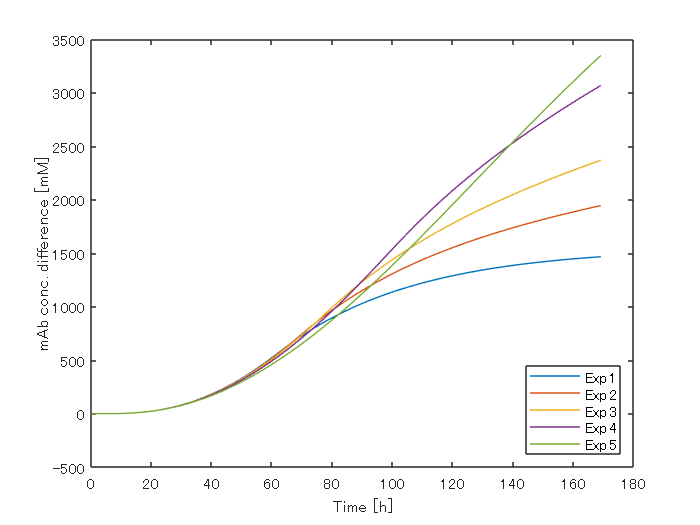

figure
for expIdx = 1:5
    plot(mAbDifferenceLog(expIdx).Values.Time,mAbDifferenceLog(expIdx).Values.Data)
    hold on
end
hold off
ylabel('mAb conc. difference [mM]')
xlabel('Time [h]')
legend('Exp 1','Exp 2','Exp 3','Exp 4','Exp 5','Location','SouthEast')

## Define the Estimation Objective

estFcn = @(p) compareModels_Objective(p,Simulator,Exp);

## Estimate the Parameters

Use the `sdo.optimize` function to estimate the actuator parameter values and initial state. 

Specify the optimization options. The estimation function `sdoMassSpringDamper_Objective` returns the error residuals between simulated and experimental data and does not include any constraints, making this problem ideal for the `lsqnonlin` solver.

option = sdo.OptimizeOptions;
option.Method = 'lsqnonlin';
% opt.Method = 'fmincon';
% opt.Method = 'patternsearch';
% opt.Method = 'surrogateopt';

Estimate the parameters. Notice that the initial mass position is estimated twice, once for each experiment.

pOpt = sdo.optimize(estFcn,p,option)


 最適化開始時間 22-Oct-2022 23:50:55

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0      5  1.62066e+09            1                                         
    1     10  2.09646e+06       0.7353     8.59e+03
    2     15  2.08083e+06       0.9736          493
    3     20  2.07989e+06       0.2435         24.5
局所的最小値の可能性があります。

二乗和において、その初期値からの最終的な変化量が
関数の許容誤差値未満であるため、lsqnonlin は停止しました。
 
pOpt(1,1) =
 
       Name: 'Y_mAb_X'
      Value: 3.0583e-12
    Minimum: 0
    Maximum: Inf
       Free: 1
      Scale: 9.3132e-10
       Info: [1×1 struct]

 
pOpt(2,1) =
 
       Name: 'mnt_mAb'
      Value: 1.1989e-08
    Minimum: 0
    Maximum: Inf
       Free: 1
      Scale: 1.4901e-08
       Info: [1×1 struct]

 
2x1 param.Continuous
 
lists of methods, superclasses
 


## Compare the Measured Output and the Final Simulated Output

Update the experiments with the estimated parameter values.

Exp  = setEstimatedValues(Exp,pOpt);

signalLoggingName = get_param('compareModels','SignalLoggingName');

mAbDifferenceLog = Simulink.SimulationData.Signal;
for expIdx = 1:5
    Simulator = createSimulator(Exp(expIdx));
    Simulator = sim(Simulator);
    
    SimLog = find(Simulator.LoggedData,signalLoggingName);
    mAbDifferenceLog(expIdx) = find(SimLog,'mAbDifference');
end

Plot the measured and simulated data.

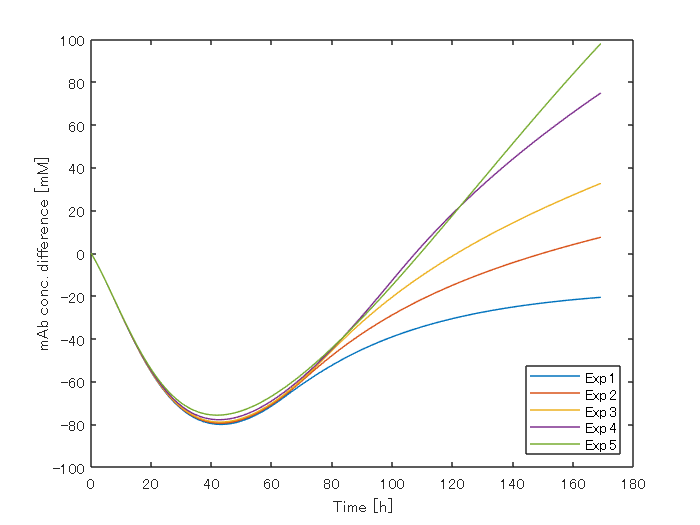

figure
for expIdx = 1:5
    plot(mAbDifferenceLog(expIdx).Values.Time,mAbDifferenceLog(expIdx).Values.Data)
    hold on
end
hold off
ylabel('mAb conc. difference [mM]')
xlabel('Time [h]')
legend('Exp 1','Exp 2','Exp 3','Exp 4','Exp 5','Location','SouthEast')

## Update the Model Parameter Values

Update the model `m`, `k`, and `b` parameter values. Do not update the model initial position value as this is dependent on the experiment.

sdo.setValueInModel('compareModels',pOpt);

Close the model

% bdclose('compareModels')

*Copyright 2012-2016 The MathWorks, Inc.*